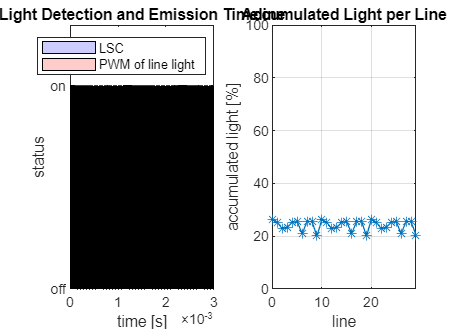

% variables
freq_LSC = 10000;
freq_line_light = 47000;
duty_LSC = 80;
duty_line_light = 30;
num_periods = 30;
time_res = 10000;
offset = 0;

% calculate time vector
t = linspace(0, num_periods/freq_LSC, time_res);

% calculate offset index
offset_index = round((offset/100)*(time_res/num_periods));

% calculate PWM functions
fun_LSC = PWM(freq_LSC, 0, 1, duty_LSC, t);
fun_line_light = PWM(freq_line_light, offset_index, 1, duty_line_light, t);

% calculate average light for every period
exp_value = zeros(num_periods, 1);
for i = 1:num_periods
    cum_val = 0;
    for n = floor(i*(time_res/num_periods)-(time_res/num_periods)) + 1:floor(i*(time_res/num_periods))
        cum_val = cum_val + fun_LSC(n)*fun_line_light(n);
    end
    exp_value(i) = cum_val*100/(time_res/num_periods);
end

% Plot when LSC has sensor open and when Line light is emmiting light.
subplot(1,2,1)
plot(t, fun_LSC)
hold on
fill_handle_LSC = fill([t fliplr(t)], [fun_LSC zeros(size(fun_LSC))], 'b', 'FaceAlpha', 0.2);
plot(t, fun_line_light)
fill_handle_line_light = fill([t fliplr(t)], [fun_line_light zeros(size(fun_line_light))], 'r', 'FaceAlpha', 0.2);
hold off

title("Light Detection and Emission Timeline")
set(gca, 'ytick', [0 1])
set(gca, 'yticklabel', {'off', 'on'})
xlabel("time [s]")
ylabel("status")
ylim([0, 1.3])
legend([fill_handle_LSC fill_handle_line_light], {'LSC','PWM of line light'},'Location', 'northeast')

% Plot collected light for every frame.
subplot(1,2,2)
plot(0:length(exp_value)-1, exp_value, '*-')

ylim([0, 100])
title("Accumulated Light per Line")
xlabel("line")
%xticks(0:ceil(num_periods/10):num_periods)
ylabel("accumulated light [%]")
grid on